# Numerical continuation on RDC surrogate model

The single-wave modes of RDC model are continuated with the aim of solving all possible distributions of single-wave modes under different the injection–mixing parameter ($\beta$).

## 1 load profiles from transient simulation

The initial condition is obtained from a steady single-wave state computed by the partial differential equation (PDE) solver at $\beta =0\ldotp 08$. Since the PDE-computed state is not strictly steady and the monitoring of the wave speed involves inherent inaccuracies, the PDE solution cannot be directly employed as the starting point for continuation. Instead, it must be used as the initial guess for a Newton iteration, through which an accurate single-wave solution consistent with the PDE state is obtained. This refined solution then serves as the starting point for the continuation procedure.

addpath(genpath(fileparts(pwd)))
load('sim_profiles_at_beta_008.mat');
global Ks Kx M gamma nx dx
%these parameters should be consistent with transient simulations
L = 24;                    
nx = 2400;                 
gamma = 1.29;
beta0 = 0.08; %the parameter under which the transient simulation was conducted
s0 = -2.8; %initial guess for wave speed, measured by the slope in t-x diagrams.
[Ks,Kx,M] = getStiff(L,nx);
dx = L/nx;
xc = linspace(0+0.5*dx,24-0.5*dx,nx);
y0 = [q_init;s0];
uref = y0;
[sol,tol] = eqnSolver(y0,beta0);
fprintf('Iteration residuals down to %e\n',tol)

Iteration residuals down to 7.138339e-07


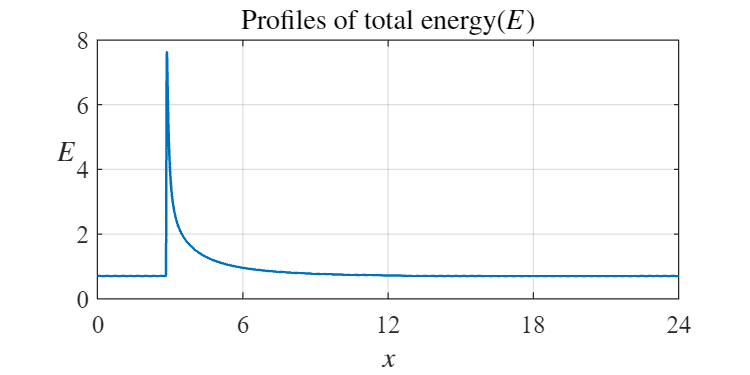

%sol contains both conservative variables (rho,rhou,E,rhoz) and wave speed(s)
%rho = sol(1:nx);rhou = sol(nx+1:2*nx);...;s = sol(end);
%sol is an accurate solution for surrogate model under wave speed
%coordinates(X = x-st).
figure('Position', [100 100 400 200]);
plot(xc,sol(2*nx+1:3*nx),'LineWidth',1)
grid on
xlim([0 L])
xl = xlabel('$x$');yl = ylabel('$E$','Rotation',0);
xticks([0 6 12 18 24])
set(xl,'Interpreter','latex');set(yl,'Interpreter','latex');
set(gca,'fontName','Times New Roman')
set(gca,'fontSize',10)
tl = title('Profiles of total energy($E$)');
set(tl,'Interpreter','latex')

## 2 Obtain the initial tangent vector $\tau$

After obtaining an accurate initial solution in step 1, this solution is taken as the starting point for continuation. However, it is also necessary to determine the continuation direction of the solution branch before proceeding, which is governed by the initial tangential vector.

tau0 = tau0_Solver(uref,sol,beta0,'backward');
tau_init = tau0;
[sol,beta0,~,tol] = cont_one_step(tau0,sol,beta0,uref,0.001);
solinit = sol;beta_init = beta0;
%solinit,beta_init and tau_init together constitute the starting point for continuation.

## 3.1 Main loop for continuations (positive ds)

Based on the previously determined initial point and initial tangent vector, the continuation of the function is initiated with the prescribed continuation step size (ds) and the specified number of continuation steps (step1).

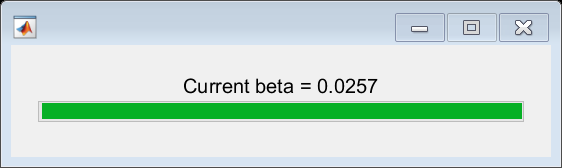

h = waitbar(0, 'Initializing...');
tau0 = tau_init;sol = solinit;beta0 = beta_init;
ds = 0.25;
step1 = 100;
Sol1 = cell([step1,1]);
beta_list1 = zeros(step1,1);
%Continuation Loop
for i = 1:step1
    [u,beta,tau,tol] = cont_one_step(tau0,sol,beta0,uref,ds);
    if sum(isnan(u))>0
        break
    end
    Sol1{i} = u;
    beta_list1(i) = beta;
    waitbar(i / step1, h, ['Current beta = ', num2str(round(beta,4))]);
    sol = u; beta0 = beta; tau0 = tau;
end

## 3.2 Main loop for continuations (negative ds)

Continuate towards opposite directions

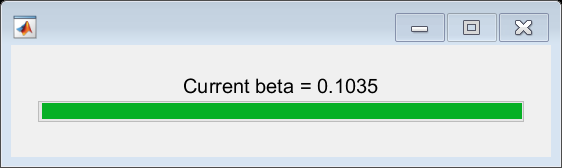

h = waitbar(0, 'Initializing...');
tau0 = tau_init;sol = solinit;beta0 = beta_init;
ds = -0.25;
step2 = 100;
Sol2 = cell([step2,1]);
beta_list2 = zeros(step2,1);
%Continuation Loop
for i = 1:step2
    [u,beta,tau,tol] = cont_one_step(tau0,sol,beta0,uref,ds);
    if sum(isnan(u))>0
        break
    end
    Sol2{i} = u;
    beta_list2(i) = beta;
    waitbar(i / step2, h, ['Current beta = ', num2str(round(beta,4))]);
    sol = u; beta0 = beta; tau0 = tau;
end

## 4 Get bifurcation diagram

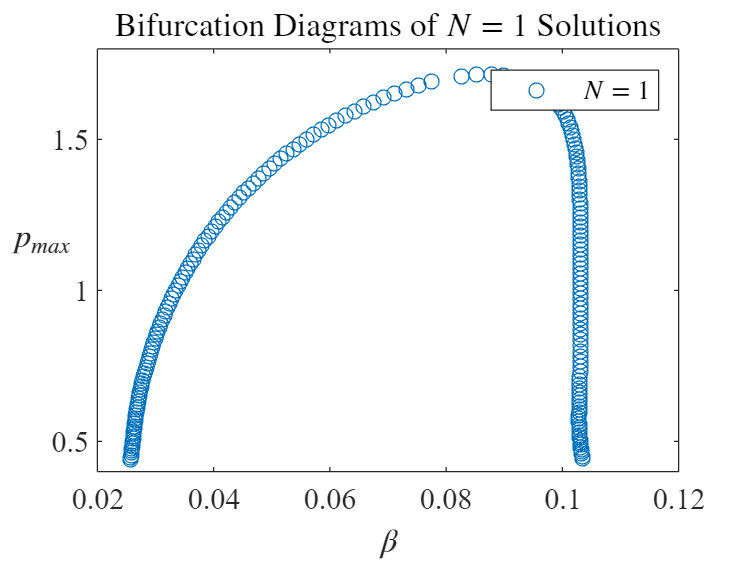

step = step1 + step2;
Sol = cell([step,1]);
for i = 1:step1
    Sol{i,1} = Sol1{i,1};
end
for i = 1:step2
    Sol{i+step1,1} = Sol2{i,1};
end
beta_list = [beta_list1(1:step1);beta_list2(1:step2)];
pmax = zeros([step,1]);
for i = 1:step
    utmp = Sol{i,1};
    p = (gamma-1)*(utmp(2*nx+1:3*nx)-0.5*utmp(nx+1:2*nx).^2./utmp(1:nx));
    pmax(i) = norm(p,'inf');
end
figure('Position', [100 100 400 300]);
plot(beta_list(1:step),pmax,'o')
lg = legend('$N$ = 1');
set(lg,'Interpreter','latex')
xl = xlabel('$\beta$');yl = ylabel('$p_{max}$','Rotation',0);
set(xl,'Interpreter','latex');set(yl,'Interpreter','latex');
tl = title('Bifurcation Diagrams of $N$ = 1 Solutions');
set(tl,'Interpreter','latex');
set(gca,'fontName','Times New Roman')
set(gca,'fontSize',12)

## 5 Analyse linear stability of a given mode

case_number = 1;

case_number = 1

base_sol = Sol1{case_number,1};
A = full(equationJac(base_sol(1:end-1),base_sol(end),beta_list1(case_number)));
[V,D] = eig(A);%A is relatively big, the solution process may take a while (around 3 minutes for nx=2400).

错误使用 image
不支持复数值。请将颜色数据指定为数值或逻辑值。

## Plot eigenvalue specturm

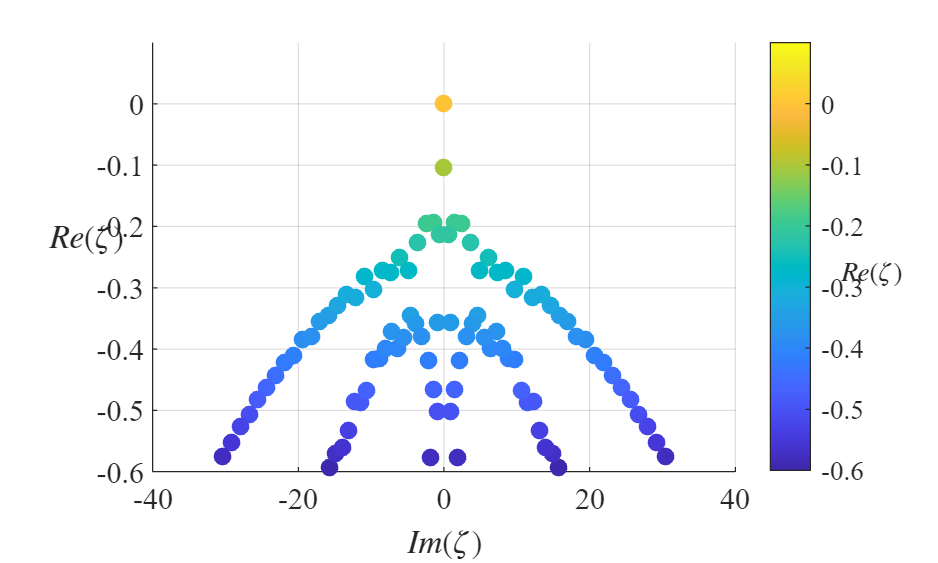

figure('Position', [100 100 500 300]);
d = diag(D);
rd = real(d);
id = imag(d);
scatter(id,rd,50,rd,'filled')
clim([-0.6 0.1]);   % 设置颜色映射的范围
ylim([-0.6 0.1]);
grid on;
xl = xlabel('$Im (\zeta)$');yl = ylabel('$Re (\zeta)$','Rotation',0);
set(xl,'Interpreter','latex');set(yl,'Interpreter','latex');
set(gca,'fontName','Times New Roman')
set(gca,'fontSize',12)
h = colorbar;
h.Label.String = '$Re (\zeta)$';
h.Label.Interpreter = 'latex';
h.Label.Rotation = 0;